# Polarization and its applications

[EE551 - Spring 2021 - Tutorial 3 - Polarization and its applications ](https://github.com/SrikanthS-IIT/EE551-Tutorials-Spring2021/blob/main/EE551-Spring%202021-Tutorial3_Polarization%20and%20its%20applications.mlx)© 2021 by [Srikanth Sugavanam ](http://www.srikanthsugavanam.com/)is licensed under [CC BY-NC 4.0    ](http://creativecommons.org/licenses/by-nc/4.0/?ref=chooser-v1)

## Malus's law

For incident linearly polarized light, Malus's law relates the intensity of light transmitted $I\left(\theta \right)$ by a polarizer to the angle of inclination of the polarizer pass axis $\theta \;$


$$I\left(\theta \;\right)=I_0 \;{\mathrm{cos}}^{2\;} \theta \;\ldotp$$


### Problem 1 - Using Jones's vectors and matrices for verifying Malus's law

For the configuration below, using Jones vectors and matrices, write a code to plot the intensity at the output analyzer as it is rotated through 0 to 180 degrees. 

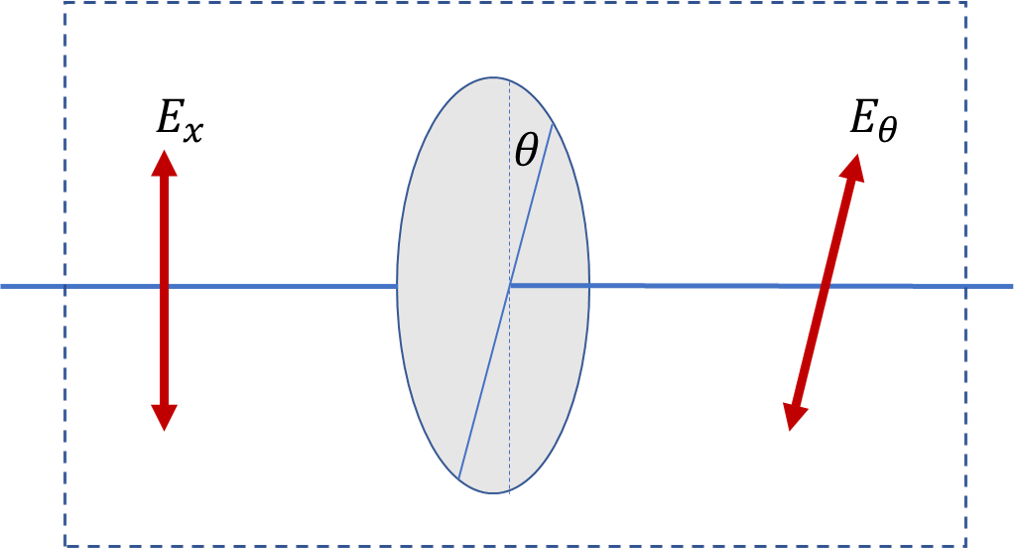

## Double refraction

### Introduction

When light is incident from free space onto a birefringent (uniaxial) crystal, it experiences double refraction inside the crystal, giving rise to an o-ray and an e-ray. The directions of the o- and the e-ray depend on the relative orientation of the optic axis (OA) with respect to the angle of incidence of the light ray coming in from free space. The objective of this set of coding exercise is to determine the angular separation between the o- and e-ray inside the crystal. For simplicity, we will assume that the crystal is cut such that the OA is in the cleavage plane, while it may describe an angle with the end-facet. This is usually the case for most commercially available components made with birefringent crystals. 

### Foundations

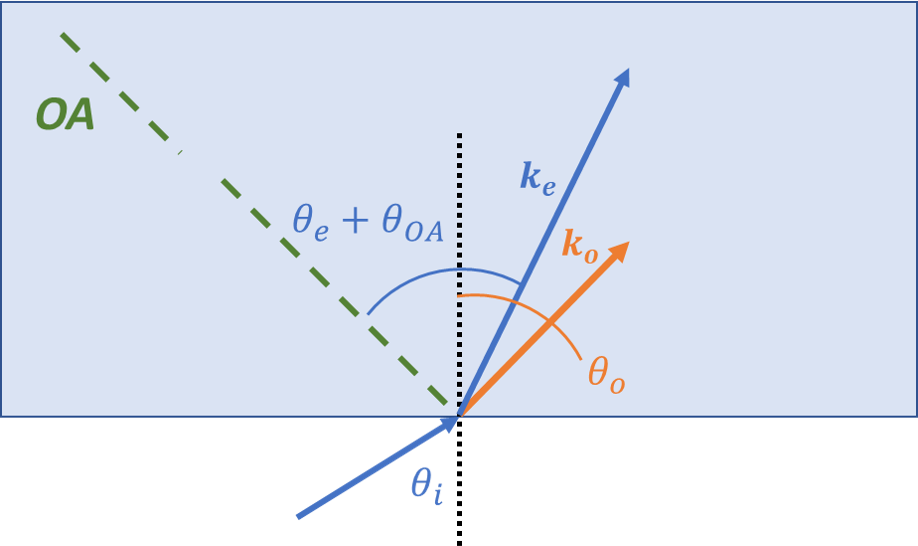

#### Snell's law

The conceptual basis of the analysis is that the k-vectors for the o- and e-rays obey the field continuity equations, and hence the Snell's law. 

For the o-ray, the Snell's law gives us (Eq. 1)


$$n_i \sin \theta_i =n_o \sin \theta_o$$


For the e-ray, the Snell's law gives us (Eq. 2)


$$n_i \sin \theta_i =n_e \left(\theta_e +\theta_{\textrm{OA}} \right)\sin \theta_e \ldotp$$


(Pay attention to how the refractive index and the refraction angle is defined.) 

The refractive index $n_e$is a function of the angle the k-vector makes with the OA, and is given by (Eq. 3)


$$\frac{1}{n_e^2 \left(\theta_e +\theta_{\textrm{OA}} \right)}=\frac{\cos^2 \left(\theta_e +\theta_{\textrm{OA}} \right)}{n_o^2 }+\frac{\sin^2 \left(\theta_e +\theta_{\textrm{OA}} \right)}{n_e^2 }\ldotp$$


Eq. 2 and Eq. 3 can be combined to obtain a value of $\theta_e$.

#### Distinction between k-waves and the refracted rays

The equations above give the direction of the k-waves inside the crystal. However, in a birefringent crystal, the ${\mathit{\mathbf{k}}}_{\mathit{\mathbf{e}}}$- and $\mathit{\mathbf{S}}$-vectors for the e-ray are not parallel like they usually are in free space. The S-vector describes the direction of energy flow, and hence the direction of the e-ray deviates from that of k-wave. 

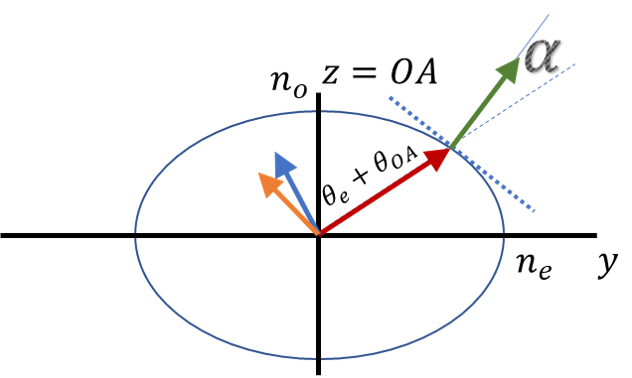

For a uniaxial crystal where the OA is in the plane of incidence (like the configuration above), the angular separation between ${\mathit{\mathbf{k}}}_{\mathit{\mathbf{e}}}$ and $\mathit{\mathbf{S}}$ is given by the angle $\alpha \;$(Eq. 4) 


$$\tan \alpha =\frac{\left(n_e^2 -n_o^2 \right)\tan \left(\theta_e +\theta {\;}_{\textrm{OA}} \right)}{n_e^2 +n_o^2 \tan^2 \left(\theta_e +\theta_{\textrm{OA}} \right)}\ldotp$$


Thus with a knowledge of the angle $\theta_e$, the angular separation between the e- and o-rays can be determined. 

### Problem 1 - Direction of the e-propagation vector ${\mathit{\mathbf{k}}}_{\mathit{\mathbf{e}}}$ 

Use Eq. 2 and Eq.3 to determine the direction of the k-vector. For this, treat $\theta_{\textrm{OA}}$, $\theta_i$, $n_o$and $n_e$ as parameters that can be entered in the code by the user. You know from class that you can define an identity equation of the form


$$n_i \sin \theta_i ={\left\lbrack \frac{\cos^2 \left(\theta_e +\theta_{\textrm{OA}} \right)}{n_o^2 }+\frac{\sin^2 \left(\theta_e +\theta_{\textrm{OA}} \right)}{n_e^2 }\right\rbrack }^{-\frac{1}{2}} \sin \theta_e \ldotp$$


The left and right hand sides of the above equations should equal for a particular value of $\theta_e$. Hence, using the above equation, find $\theta_e$. 

n_i = 1;
n_o = 1.55;
n_e = 1.65;
theta_i = 30*pi/180;
theta_OA = 18.5*pi/180;

%... Enter your code below

### Problem 2 - Determination of the angular separation between the ray and the wave $\alpha \;$

Having determined the value of $\theta_e$ from the above Task, determine the value of $\alpha$ using Eq. 4 above. 